# Curve Fitting and Derivative Estimation from Noisy Data

## 1. Problems with Finite Difference

Derivatives are crucial information for many engineering problems. However, estimating derivatives directly from experimental

data using finite differences can amplify the noise in the measurements, making the estimation unreliable. 

Let's try using forward differences to observe the effect.

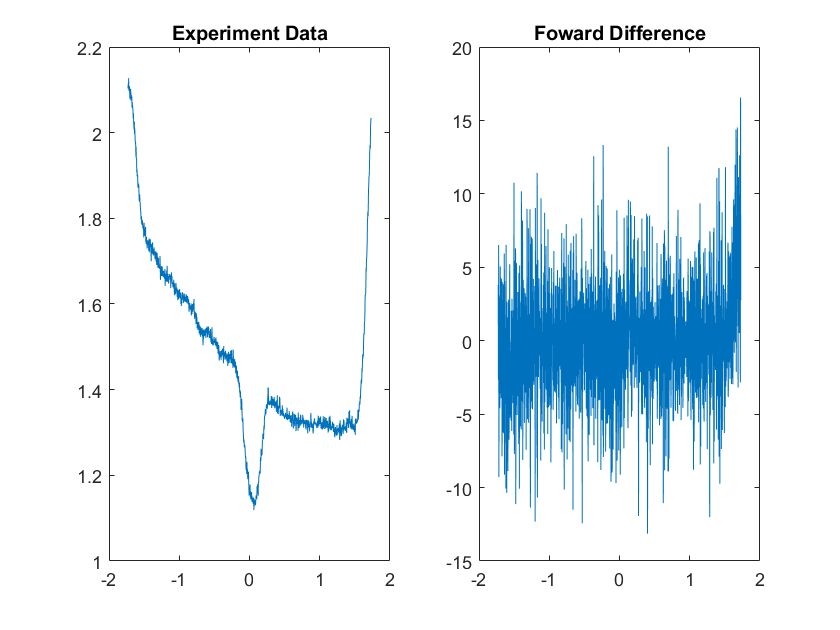

% Visualize data
clear; clc; close all;
load('Experiment.mat');
data=Experiment.Data;
label=Experiment.Label;
subplot(1,2,1)
plot(data,label)
title('Experiment Data')

dy=diff(label); FDestimate=dy/(data(2)-data(1));
subplot(1,2,2)
plot(data(1:end-1),FDestimate)
title('Foward Difference')

An alternative approach is to first smooth the data and then apply finite differences again. 

While this approach can effectively reduce noise, it is important to note that smoothing the data may also introduce distortion.

## 2. Denoising using Neural Networks

Curve fitting is another viable method,  in order to capture the essential patterns, 

the fitted curve must effectively filter out the noise without excessively smoothing the data, 

This is where neural networks (NNs) come into play.

% NN Set Up
NN.Cost='SSE';
NN.LabelAutoScaling='on';
InputDimension=1; OutputDimension=1;
LayerStruct=[InputDimension,10,60,OutputDimension];
NN=Initialization(LayerStruct,NN);
% Solver Set Up
option.MaxIteration=800;
option.Solver='Auto';
NN=OptimizationSolver(data,label,NN,option);

Iteration : 10 , Cost :     384.49729565 
Iteration : 20 , Cost :     212.65560568 
Iteration : 30 , Cost :     210.30027598 
Iteration : 40 , Cost :     208.72765439 
Iteration : 50 , Cost :     207.55258793 
Iteration : 60 , Cost :     206.95243799 
Iteration : 70 , Cost :     205.91134781 
Iteration : 80 , Cost :     206.50868341 
Iteration : 90 , Cost :     204.38165467 
Iteration : 100 , Cost :     203.38677899 
Iteration : 110 , Cost :     205.26074168 
Iteration : 120 , Cost :     200.31847759 
Iteration : 130 , Cost :     198.08621115 
Iteration : 140 , Cost :     200.15510198 
Iteration : 150 , Cost :     192.89599156 
Iteration : 160 , Cost :     189.19243171 
Iteration : 170 , Cost :     185.22750214 
Iteration : 180 , Cost :     183.93671967 
Iteration : 190 , Cost :     177.69751466 
Iteration : 200 , Cost :     174.25634731 
------------------------------------------------------
First Stage Optimization Finished in  200  Iteration.
----------------------------------------

It can be observed that **neural networks are capable of **

**filtering out noise while preserving essential patterns in the data**.

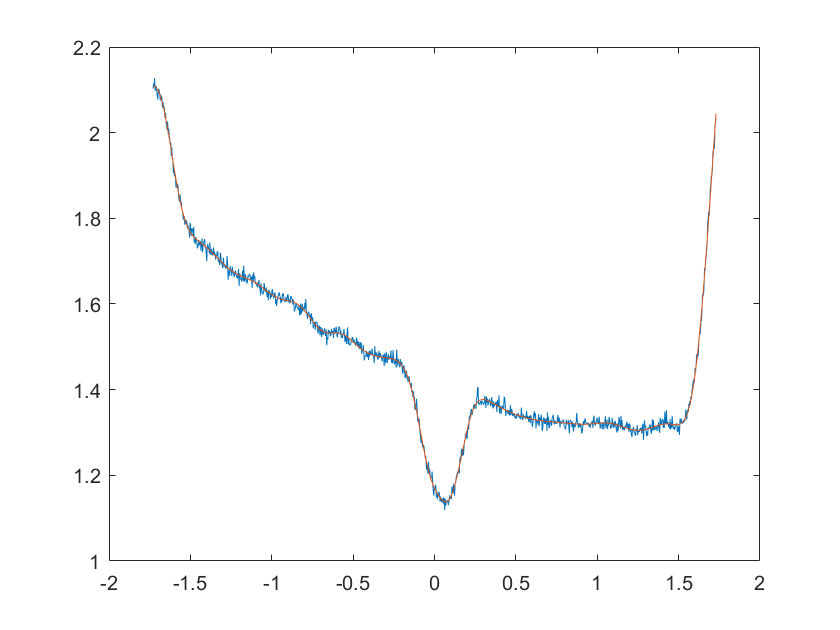

prediction=NN.Evaluate(data);
figure
plot(data,label)
hold on
plot(data,prediction)

## 3. Computing Derivate of Neural Networks

Compute Derivate using `NN.Derivate `function.

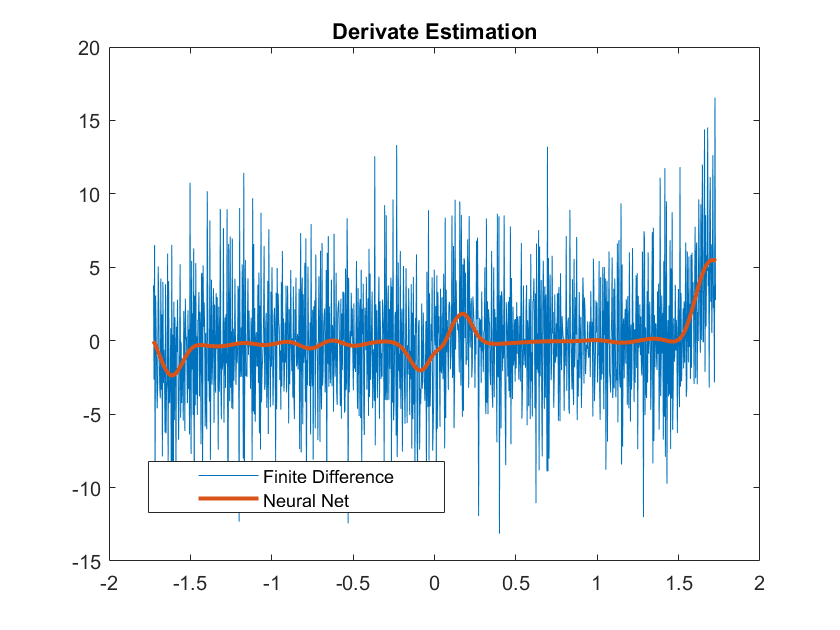

NNestimate=NN.Derivate(data(1:end-1));
% Compare with Finite Difference
figure
plot(data(1:end-1),FDestimate);
hold on
plot(data(1:end-1),NNestimate,"LineWidth",2)
legend('Finite Difference','Neural Net')
legend("Position", [0.17655,0.18611,0.35357,0.082143])
title('Derivate Estimation')

(note that the functionality of `NN.Derivate` is to compute $\frac{\partial \textrm{NN}}{\partial \mathit{\mathbf{x}}}$, not $\frac{\partial \textrm{NN}}{\partial \;\mathit{\mathbf{W}}},\frac{\partial \textrm{NN}}{\partial \;\mathit{\mathbf{b}}}$)

The function "`NN.Derivate`" implements the complex step algorithm for calculating derivatives and

can be extended to multivariable functions $\textrm{NN}\left(\mathit{\mathbf{x}}\right):R^n \to R^m$ as well. 

i.e. Jacobian (if $m=1$, then $\mathit{\mathbf{J}}$ became gradient of $\mathit{\mathbf{f}}$)


$$\textrm{NN}\left(\mathit{\mathbf{x}}\right):R^n \to R^m ,\mathit{\mathbf{J}}\left(\mathit{\mathbf{x}}\right)=\left\lbrack \begin{array}{ccc}
\frac{\partial \;{\textrm{NN}}_1 }{\partial x_1 } & \cdots  & \frac{\partial \;{\textrm{NN}}_1 }{\partial x_n }\\
\vdots  & \ddots  & \vdots \\
\frac{\partial \;{\textrm{NN}}_m }{\partial x_2 } & \cdots  & \frac{\partial \;{\textrm{NN}}_m }{\partial x_n }
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
{\nabla {\textrm{NN}}_1 }^T \\
\vdots \\
{\nabla {\textrm{NN}}_m }^T 
\end{array}\right\rbrack$$


like most commands in MATLAB, NN.Derivate supprot matrix input, given a $N\times p$ matrix, where $p$ is number of input data points,

the function will output a $n\times p\times m$ matirx $\mathit{\mathbf{D}}$, and $\mathit{\mathbf{D}}\left(:,:,k\right)$ represent gradient of ${\textrm{NN}}_k \left(\mathit{\mathbf{x}}\right)$ evaluate at each given point ${\mathit{\mathbf{x}}}_j$.


$$\mathit{\mathbf{D}}\left(:,:,k\right)=\left\lbrack \begin{array}{cccc}
\nabla {\textrm{NN}}_k \left({\mathit{\mathbf{x}}}_1 \right) & \nabla {\textrm{NN}}_k \left({\mathit{\mathbf{x}}}_2 \right) & \cdots  & \nabla {\textrm{NN}}_k \left({\mathit{\mathbf{x}}}_p \right)
\end{array}\right\rbrack ,\nabla {\textrm{NN}}_k \left({\mathit{\mathbf{x}}}_j \right)\in R^{n\times 1}$$


With the ability to compute the derivatives of neural networks, we can apply them to various fields such as 

Surrogate Optimization and solving PDEs using neural nets (Physical-Informed Neural Networks, PINN). 